#  Dynamics of Dual Copter System

## Initializing

In this section we will be defining symbolic variables as need for our dual copter paired system

clear;clc;close all

% States
syms x y z phi theta psi...
    x_dot y_dot z_dot phi_dot theta_dot psi_dot ...
    x_ddot y_ddot z_ddot phi_ddot theta_ddot psi_ddot ...
    real

% Physics
syms m_c I_x_c I_y_c I_z_c  m_t I_x_t I_y_t I_z_t Lx_ir Ly_ir Lx_or Ly_or L_c I_l w g real


% Inputs
syms tau_1 tau_2 real

% q is defined as orientation and position of center frame
q = [x;y;z;phi; theta; psi]

$$q = \left(\begin{array}{c} x\\ y\\ z\\ \varphi \\ \theta \\ \psi \end{array}\right)$$

dq = [x_dot;y_dot;z_dot;phi_dot; theta_dot; psi_dot]

$$dq = \left(\begin{array}{c} \dot{x}\\ \dot{y}\\ \dot{z}\\ \dot{\varphi }\\ \dot{\theta }\\ \dot{\psi } \end{array}\right)$$

ddq = [ x_ddot ; y_ddot ; z_ddot;phi_ddot; theta_ddot; psi_ddot]

$$ddq = \left(\begin{array}{c} \ddot{x}\\ \ddot{y}\\ \ddot{z}\\ \ddot{\varphi }\\ \ddot{\theta }\\ \ddot{\psi } \end{array}\right)$$

Our IMU will provide Tait Bryan Angles of our system, and the Flowdeck will return x y z. These results will be used to compute q directly.

%% W to com truss

gw1 = [eye(3)      [x;y;z]
        zeros(1,3)          1];
g12 =[rotationMatrix(-phi,'x') [0;0;0]
        zeros(1,3)          1];
g23 = [rotationMatrix(-theta,'y') [0;0;0]
        zeros(1,3)          1];
g3t = [rotationMatrix(-psi,'z') [0;0;0]
        zeros(1,3)          1];
gwt = simplify(gw1*g12*g23*g3t)

$$gwt = \left(\begin{array}{cccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & -\sin\left(\theta \right) & x\\ \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & y\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & z\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%% W to com crazy flie1

gtc_1 = [eye(3)      [0;-L_c;0]
        zeros(1,3)          1];
gwc_1 = simplify(gwt*gtc_1)

$$gwc\_1 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & -\sin\left(\theta \right) & x-L_{c}\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sigma_{1} & \cos\left(\theta \right)\,\sin\left(\varphi \right) & y-L_{c}\,\sigma_{1}\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \sigma_{2}-\sigma_{3} & \cos\left(\varphi \right)\,\cos\left(\theta \right) & z+L_{c}\,\left(\sigma_{3}-\sigma_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{2}=\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{3}=\cos\left(\psi \right)\,\sin\left(\varphi \right) \end{array}$$


% W to com crazy flie2
gtc_2 = [eye(3)      [0;L_c;0]
        zeros(1,3)          1];
gwc_2 = simplify(gwt*gtc_2)

$$gwc\_2 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & -\sin\left(\theta \right) & x+L_{c}\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sigma_{1} & \cos\left(\theta \right)\,\sin\left(\varphi \right) & y+L_{c}\,\sigma_{1}\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \sigma_{2}-\sigma_{3} & \cos\left(\varphi \right)\,\cos\left(\theta \right) & z-L_{c}\,\left(\sigma_{3}-\sigma_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{2}=\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{3}=\cos\left(\psi \right)\,\sin\left(\varphi \right) \end{array}$$

%Jacobian of Copter 1
gwc1_inv = simplify(inv(gwc_1));
J1 = simplify(rbvel2twist(gwc1_inv*diff(gwc_1,x)));
J2 = simplify(rbvel2twist(gwc1_inv*diff(gwc_1,y)));
J3 = simplify(rbvel2twist(gwc1_inv*diff(gwc_1,z)));
J4 = simplify(rbvel2twist(gwc1_inv*diff(gwc_1,phi)));
J5 = simplify(rbvel2twist(gwc1_inv*diff(gwc_1,theta)));
J6 = simplify(rbvel2twist(gwc1_inv*diff(gwc_1,psi)));
Jc1 = [J1 J2 J3 J4 J5 J6]

$$Jc1 = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{2} & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & L_{c}\,\sin\left(\theta \right) & 0 & -L_{c}\\ \sigma_{1} & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & 0 & 0 & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & L_{c}\,\cos\left(\psi \right)\,\cos\left(\theta \right) & -L_{c}\,\sin\left(\psi \right) & 0\\ 0 & 0 & 0 & -\sigma_{2} & \sin\left(\psi \right) & 0\\ 0 & 0 & 0 & -\sigma_{1} & -\cos\left(\psi \right) & 0\\ 0 & 0 & 0 & \sin\left(\theta \right) & 0 & -1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sigma_{2}=\cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}$$


% Jacobian of Copter 2
gwc2_inv = simplify(inv(gwc_2));
J1 = simplify(rbvel2twist(gwc2_inv*diff(gwc_2,x)));
J2 = simplify(rbvel2twist(gwc2_inv*diff(gwc_2,y)));
J3 = simplify(rbvel2twist(gwc2_inv*diff(gwc_2,z)));
J4 = simplify(rbvel2twist(gwc2_inv*diff(gwc_2,phi)));
J5 = simplify(rbvel2twist(gwc2_inv*diff(gwc_2,theta)));
J6 = simplify(rbvel2twist(gwc2_inv*diff(gwc_2,psi)));
Jc2 = [J1 J2 J3 J4 J5 J6]

$$Jc2 = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{2} & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & -L_{c}\,\sin\left(\theta \right) & 0 & L_{c}\\ \sigma_{1} & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & 0 & 0 & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & -L_{c}\,\cos\left(\psi \right)\,\cos\left(\theta \right) & L_{c}\,\sin\left(\psi \right) & 0\\ 0 & 0 & 0 & -\sigma_{2} & \sin\left(\psi \right) & 0\\ 0 & 0 & 0 & -\sigma_{1} & -\cos\left(\psi \right) & 0\\ 0 & 0 & 0 & \sin\left(\theta \right) & 0 & -1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sigma_{2}=\cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}$$


% Jacobian of Truss
gwt_inv = simplify(inv(gwt));
J1 = simplify(rbvel2twist(gwt_inv*diff(gwt,x)));
J2 = simplify(rbvel2twist(gwt_inv*diff(gwt,y)));
J3 = simplify(rbvel2twist(gwt_inv*diff(gwt,z)));
J4 = simplify(rbvel2twist(gwt_inv*diff(gwt,phi)));
J5 = simplify(rbvel2twist(gwt_inv*diff(gwt,theta)));
J6 = simplify(rbvel2twist(gwt_inv*diff(gwt,psi)));

Jt = [J1 J2 J3 J4 J5 J6]

$$Jt = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{2} & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & 0 & 0 & 0\\ \sigma_{1} & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & 0 & 0 & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & 0 & 0 & 0\\ 0 & 0 & 0 & -\sigma_{2} & \sin\left(\psi \right) & 0\\ 0 & 0 & 0 & -\sigma_{1} & -\cos\left(\psi \right) & 0\\ 0 & 0 & 0 & \sin\left(\theta \right) & 0 & -1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sigma_{2}=\cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}$$

%Mass Matricies

% First Copter 
M_1 = ManipMatrix(m_c,[I_x_c,I_y_c,I_z_c])

$$M\_1 = \left(\begin{array}{cccccc} m_{c} & 0 & 0 & 0 & 0 & 0\\ 0 & m_{c} & 0 & 0 & 0 & 0\\ 0 & 0 & m_{c} & 0 & 0 & 0\\ 0 & 0 & 0 & I_{x,c} & 0 & 0\\ 0 & 0 & 0 & 0 & I_{y,c} & 0\\ 0 & 0 & 0 & 0 & 0 & I_{z,c} \end{array}\right)$$


% Second Copter
M_2 = ManipMatrix(m_c,[I_x_c,I_y_c,I_z_c])

$$M\_2 = \left(\begin{array}{cccccc} m_{c} & 0 & 0 & 0 & 0 & 0\\ 0 & m_{c} & 0 & 0 & 0 & 0\\ 0 & 0 & m_{c} & 0 & 0 & 0\\ 0 & 0 & 0 & I_{x,c} & 0 & 0\\ 0 & 0 & 0 & 0 & I_{y,c} & 0\\ 0 & 0 & 0 & 0 & 0 & I_{z,c} \end{array}\right)$$


% Truss 
M_3 = ManipMatrix(m_t,[I_x_t,I_y_t,I_z_t])

$$M\_3 = \left(\begin{array}{cccccc} m_{t} & 0 & 0 & 0 & 0 & 0\\ 0 & m_{t} & 0 & 0 & 0 & 0\\ 0 & 0 & m_{t} & 0 & 0 & 0\\ 0 & 0 & 0 & I_{x,t} & 0 & 0\\ 0 & 0 & 0 & 0 & I_{y,t} & 0\\ 0 & 0 & 0 & 0 & 0 & I_{z,t} \end{array}\right)$$

% Lagrangian Dynamics
disp(size(Jc1))

     6     6



disp(size(Jc2))

     6     6



%Combining all for T_g
T = simplify(0.5 * dq' * (Jc1' * M_1 * Jc1 + Jc2' * M_2 * Jc2 ...
    + Jt' * M_3 * Jt) * dq)


% TODO: Potential energy

% m * g * h1 + m * g * h2
h1 = gwc_1(3,4);
h2 = gwc_2(3,4);
h3 = gwt(3,4);
V = simplify(m_c*g*(h1+h2)+m_t*g*(h3))

$$V = g\,z\,\left(2\,m_{c}+m_{t}\right)$$


% TODO: Lagrangian in generalized coordinates
L = simplify(T - V)

We will largely reference a paper on the force dynamics of the crazy flie when determining the force that each rotor applies to our center truss. The paper defines this case as the following 

where fi is the force generated by each rotor, and    

tau_mi is the torque around each motor axis. we will be ignoring the drag constant as it is negligable against other forces

we will define a wrench using these definitions and transforms to move these forces to the center frame of our truss whose position is defined by q

we will also we leveraging the following two relationships from the paper

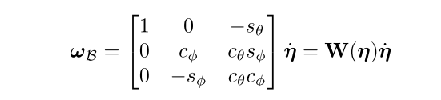 and

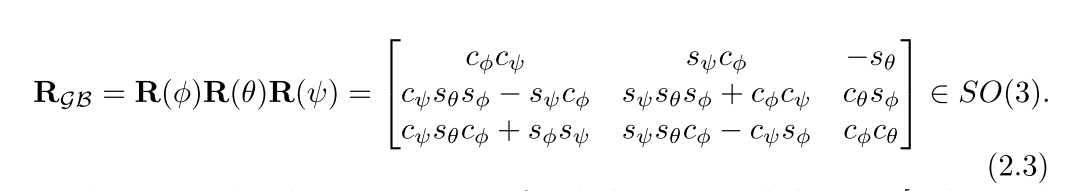

in mapping from eta_dot to Vb_wt (Body Velocity of truss wrt the world)

Where 

% % Wrench from each thruster
% syms k I_r ... %Constant defined in paper , Moment of Inertia Rotor
%     omega_1 omega_2 omega_3 omega_4 omega_5 omega_6 omega_7 omega_8... %Rotor Speeds
%     omega_dot_1 omega_dot_2 omega_dot_3 omega_dot_4 omega_dot_5 omega_dot_6 omega_dot_7 omega_dot_8 %Rotor Accelerations
% 
% % Some of these will need to be changed to negative
% F_1 = [0;0;k*omega_1^2;0;0;-I_r*omega_dot_1];
% F_2 = [0;0;k*omega_2^2;0;0;I_r*omega_dot_2];
% F_3 = [0;0;k*omega_3^2;0;0;I_r*omega_dot_3];
% F_4 = [0;0;k*omega_4^2;0;0;-I_r*omega_dot_4];
% F_5 = [0;0;k*omega_5^2;0;0;-I_r*omega_dot_5];
% F_6 = [0;0;k*omega_6^2;0;0;I_r*omega_dot_6];
% F_7 = [0;0;k*omega_7^2;0;0;I_r*omega_dot_7];
% F_8 = [0;0;k*omega_8^2;0;0;-I_r*omega_dot_8];
% 
% % Transformations 
% gtr1= [eye(3)      [Lx_or;Ly_or;0]
%         zeros(1,3)          1];
% gtr2=[eye(3)      [Lx_ir;Ly_ir;0]
%         zeros(1,3)          1];
% gtr3=[eye(3)      [Lx_or;-Ly_or;0]
%         zeros(1,3)          1];
% gtr4=[eye(3)      [-Lx_ir;-Ly_ir;0]
%         zeros(1,3)          1];
% gtr5= [eye(3)      [-Lx_or;Ly_or;0]
%         zeros(1,3)          1];
% gtr6=[eye(3)      [-Lx_ir;Ly_ir;0]
%         zeros(1,3)          1];
% gtr7=[eye(3)      [-Lx_or;-Ly_or;0]
%         zeros(1,3)          1];
% gtr8=[eye(3)      [-Lx_ir;-Ly_ir;0]
%         zeros(1,3)          1];
% 
% % Going from Fi to FTi with Adjoint Transpose, total wrench will be the sum
% F_T1 = tform2adjoint(gtr1)'*F_1
% F_T2 = tform2adjoint(gtr2)'*F_2
% F_T3 = tform2adjoint(gtr3)'*F_3
% F_T4 = tform2adjoint(gtr4)'*F_4
% F_T5 = tform2adjoint(gtr5)'*F_5
% F_T6 = tform2adjoint(gtr6)'*F_6
% F_T7 = tform2adjoint(gtr7)'*F_7
% F_T8 = tform2adjoint(gtr8)'*F_8
% 
% % F_T is the sum of all FTi and is the equivalent wrench from every rotor
% F_T = F_T1 + F_T2 + F_T3 + F_T4 + F_T5 + F_T6 + F_T7 + F_T8


% % An alternate way that we can represent these wrenches is to seperate them
% % from rotations, and show as simply the force generated in the z
% % direction, as well as the torque generated along each axis. This
% % alternate may allow us to better visualize what we are controlling 
% syms F_z1 tau_phi_1 tau_theta_1 tau_psi_1 F_z2 tau_phi_2 tau_theta_2 tau_psi_2
% 
% F_c1=   [0;0;F_z1;tau_phi_1;tau_theta_1;tau_psi_1];
% F_c2 = [0;0;F_z2;tau_phi_2;tau_theta_2;tau_psi_2];
% 
% % gtc_1 and gtc_2 the transformations from individual copters to the center
% % truss were defined previously. We will use these transforms to get the
% % equivalent wrench at the center truss
% 
% F_T1 = tform2adjoint(gtc_1)'*F_c1
% F_T2 = tform2adjoint(gtc_2)'*F_c2
% 4
% F_T_two_drone = F_T1 + F_T2;

% Another possible form that may lend itself better the the power distribition 
% in the crazy flie is to represent the thrust and axis torque 
% created by each individual motor, but seperated from rotation speed. This
% is how power distribution currently breaks things up
syms F_1 F_2 F_3 F_4 F_5 F_6 F_7 F_8 ...
    tau_1 tau_2 tau_3 tau_4 tau_5 tau_6 tau_7 tau_8



%Negative tau will have to be checked and confirmed and possibly flipped

F_1	=	[0;0;F_1;0;0;tau_1];
F_2	=	[0;0;F_2;0;0;-tau_2];
F_3	=	[0;0;F_3;0;0;tau_3];
F_4	=	[0;0;F_4;0;0;-tau_4];

F_5	=	[0;0;F_5;0;0;tau_5];
F_6	=	[0;0;F_6;0;0;-tau_6];
F_7	=	[0;0;F_7;0;0;tau_7];
F_8	=	[0;0;F_8;0;0;-tau_8];




%These aree the same as the transforms as when we were considering the roations 
% of all the individual rotos

gr1= [eye(3)      [-Lx_ir;Ly_ir;0]
        zeros(1,3)          1];
gr2=[eye(3)      [Lx_or;Ly_or;0]
        zeros(1,3)          1];
gr3=[eye(3)      [Lx_or;Ly_or;0]
        zeros(1,3)          1];
gr4=[eye(3)      [-Lx_ir;Ly_ir;0]
        zeros(1,3)          1];

gr5= [eye(3)      [-Lx_or;-Ly_or;0]
        zeros(1,3)          1];
gr6=[eye(3)      [Lx_ir;-Ly_ir;0]
        zeros(1,3)          1];
gr7=[eye(3)      [Lx_ir;-Ly_ir;0]
        zeros(1,3)          1];
gr8=[eye(3)      [-Lx_or;-Ly_or;0]
        zeros(1,3)          1];




% Transform for each motor

F_T1 = tform2adjoint(gr1)'*F_1;
F_T2 = tform2adjoint(gr2)'*F_2;
F_T3 = tform2adjoint(gr3)'*F_3;
F_T4 = tform2adjoint(gr4)'*F_4;
F_T5 = tform2adjoint(gr1)'*F_5;
F_T6 = tform2adjoint(gr2)'*F_6;
F_T7 = tform2adjoint(gr3)'*F_7;
F_T8 = tform2adjoint(gr4)'*F_8;


% F_T is the sum of all FTi and is the equivalent wrench from every rotor
F_T = F_T1 + F_T2 + F_T3 + F_T4 + F_T5 + F_T6 + F_T7 + F_T8

$$F\_T = \left(\begin{array}{c} 0\\ 0\\ F_{1}+F_{2}+F_{3}+F_{4}+F_{5}+F_{6}+F_{7}+F_{8}\\ -F_{1}\,{\mathrm{Ly}}_{\mathrm{ir}}-F_{4}\,{\mathrm{Ly}}_{\mathrm{ir}}-F_{5}\,{\mathrm{Ly}}_{\mathrm{ir}}-F_{2}\,{\mathrm{Ly}}_{\mathrm{or}}-F_{8}\,{\mathrm{Ly}}_{\mathrm{ir}}-F_{3}\,{\mathrm{Ly}}_{\mathrm{or}}-F_{6}\,{\mathrm{Ly}}_{\mathrm{or}}-F_{7}\,{\mathrm{Ly}}_{\mathrm{or}}\\ F_{2}\,{\mathrm{Lx}}_{\mathrm{or}}-F_{4}\,{\mathrm{Lx}}_{\mathrm{ir}}-F_{5}\,{\mathrm{Lx}}_{\mathrm{ir}}-F_{1}\,{\mathrm{Lx}}_{\mathrm{ir}}-F_{8}\,{\mathrm{Lx}}_{\mathrm{ir}}+F_{3}\,{\mathrm{Lx}}_{\mathrm{or}}+F_{6}\,{\mathrm{Lx}}_{\mathrm{or}}+F_{7}\,{\mathrm{Lx}}_{\mathrm{or}}\\ \tau_{1}-\tau_{2}+\tau_{3}-\tau_{4}+\tau_{5}-\tau_{6}+\tau_{7}-\tau_{8} \end{array}\right)$$


Y = Jt'*simplify(F_T)

$$Y = \begin{array}{l} \left(\begin{array}{c} -\sin\left(\theta \right)\,\sigma_{3}\\ \cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sigma_{3}\\ \cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sigma_{3}\\ \sin\left(\theta \right)\,\left(\tau_{1}-\tau_{2}+\tau_{3}-\tau_{4}+\tau_{5}-\tau_{6}+\tau_{7}-\tau_{8}\right)+\cos\left(\theta \right)\,\sin\left(\psi \right)\,\sigma_{2}+\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sigma_{1}\\ \cos\left(\psi \right)\,\sigma_{2}-\sin\left(\psi \right)\,\sigma_{1}\\ \tau_{2}-\tau_{1}-\tau_{3}+\tau_{4}-\tau_{5}+\tau_{6}-\tau_{7}+\tau_{8} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=F_{1}\,{\mathrm{Ly}}_{\mathrm{ir}}+F_{4}\,{\mathrm{Ly}}_{\mathrm{ir}}+F_{5}\,{\mathrm{Ly}}_{\mathrm{ir}}+F_{2}\,{\mathrm{Ly}}_{\mathrm{or}}+F_{8}\,{\mathrm{Ly}}_{\mathrm{ir}}+F_{3}\,{\mathrm{Ly}}_{\mathrm{or}}+F_{6}\,{\mathrm{Ly}}_{\mathrm{or}}+F_{7}\,{\mathrm{Ly}}_{\mathrm{or}}\\ \sigma_{2}=F_{1}\,{\mathrm{Lx}}_{\mathrm{ir}}+F_{4}\,{\mathrm{Lx}}_{\mathrm{ir}}+F_{5}\,{\mathrm{Lx}}_{\mathrm{ir}}-F_{2}\,{\mathrm{Lx}}_{\mathrm{or}}+F_{8}\,{\mathrm{Lx}}_{\mathrm{ir}}-F_{3}\,{\mathrm{Lx}}_{\mathrm{or}}-F_{6}\,{\mathrm{Lx}}_{\mathrm{or}}-F_{7}\,{\mathrm{Lx}}_{\mathrm{or}}\\ \sigma_{3}=F_{1}+F_{2}+F_{3}+F_{4}+F_{5}+F_{6}+F_{7}+F_{8} \end{array}$$

% % Applied force (Leverging Paper Definitions)
% R_GB = [cos(phi)*cos(psi), sin(psi)*cos(phi), -sin(theta)
%         cos(psi)*sin(theta)*sin(phi) - sin(psi)*cos(phi), sin(psi)*sin(theta)*sin(phi) + cos(phi)*cos(psi), cos(theta)*sin(psi)
%         cos(psi)*sin(theta)*cos(phi) + sin(phi)*sin(psi), sin(psi)*sin(theta)*cos(phi) - cos(psi)*sin(phi), cos(phi)*cos(theta)];
% W_eta = [1 0 -sin(theta)
%         0 cos(phi) cos(theta)*sin(phi)
%         0 -sin(phi) cos(theta)*cos(phi)]
% 
% 
% J = [R_GB zeros(3,3)
%     zeros(3,3) W_eta]
% 
% %Applied Force
% %Using all rotations
% % Y = simplify(J'*F_T)
% %Using simplified representation
% % Y = simplify(J'*F_T_simp)
% % Using individual motor thrust and torque
% Y = simplify(J'*F_T_f_t_indv)

% EOM
EOM = jacobian(gradient(L,dq) , [q;dq])*[dq;ddq] - gradient(L,q)-Y

## Physical Values for Simplifying

% Gravity
grav = 9.8;% m/s^2

%Truss Mass
mt_small = 5*10^-3; %kg
mt_large = 7*10^-3; %kg

 
%Crazyflie Mass
m_cf = 31*10^-3; %kg
%Mass/Magnet
m_mag = 4*10^-3; %kg

%We will be considering the truss as a thin box with evenly spread mass
%across. We will be considering the drone as a smalle box with the
%assumption that all the mass in concentrated in the middle, essentially
%ignoring the inertial effects of the motors and the rotors overall.

%Crazyflie inertial properities
w_cf = 30.4*10^-3;%m
h_cf = 17.0*10^-3;%m
l_cf = 27.9*10^-3;%m

% I_roll_cf= 1/12*m_cf*(l_cf^2+h_cf^2)%kg-m^2/s;
% I_pitch_cf= 1/12*m_cf*(w_cf^2+h_cf^2)%kg-m^2/s;
% I_yaw_cf= 1/12*m_cf*(l_cf^2+w_cf^2)%kg-m^2/s;

% Inertia properties Crazyflie, From Paper
I_roll_cf= 1.395*10^-5;%kg-m^2/s
I_pitch_cf= 1.436*10^-5;%kg-m^2/s
I_yaw_cf= 2.173*10^-5;%kg-m^2/s


%Short truss inertial properties
w_st = 75.60*10^-3;% m
h_st = 3.41*10^-3;% m
l_st = 87.40*10^-3;%m
L_cs = l_st/2; %m

I_roll_st= 1/12*mt_small*(l_st^2+h_st^2)%kg-m^2/s

I_roll_st = 3.1877e-06

I_pitch_st= 1/12*mt_small*(w_st^2+h_st^2)%kg-m^2/s

I_pitch_st = 2.3862e-06

I_yaw_st= 1/12*mt_small*(l_st^2+w_st^2)%kg-m^2/s

I_yaw_st = 5.5642e-06



%Long truss inertial properties
w_lt = 75.60*10^-3;%m
h_lt = 4.54*10^-3;%m
l_lt = 190*10^-3;%m
L_cl = l_lt/2+.110/2; %m
% 
% I_roll_lt= 1/12*mt_large*(l_lt^2+h_lt^2)%kg-m^2/s
% I_pitch_lt= 1/12*mt_large*(w_lt^2+h_lt^2)%kg-m^2/s
% I_yaw_lt= 1/12*mt_large*(l_lt^2+w_lt^2)%kg-m^2/s

%Inertia Properties from Matlab Long Truss
I_roll_lt = 143365.036669 * 10^-9;%kg-m^2/s
I_pitch_lt = 4221.769311 * 10^-9;%kg-m^2/s
I_yaw_lt = 139371.185565 * 10^-9;%kg-m^2/s

% Ixx = 4221.769311	Ixy = 2901.221852	Ixz = 0.045823
% Iyx = 2901.221852	Iyy = 143365.036669	Iyz = 0.001678
% Izx = 0.045823	Izy = 0.001678	Izz = 139371.185565


% Legths for Wrench transforms
Lx = w_lt/2; % m
Ly_lt_or = .110 + l_lt/2; % m
Ly_lt_ir = l_lt/2; % m
Ly_st_or = .110 + l_st/2; % m
Ly_st_ir = l_st/2; % m

% Put all of our symbolic physical properites into an array, then put the
% actual values into a seperate array. There will be 3 total sets here. 1
% for all the symbols, 1 for all the physical properties when the truss is
% small, and 1 for all the physical properties when the truss in long 

%Creating two different state space models with substitutions 
syms F_1 F_2 F_3 F_4 F_5 F_6 F_7 F_8 ...
    tau_1 tau_2 tau_3 tau_4 tau_5 tau_6 tau_7 tau_8

symbols = [m_c, I_x_c, I_y_c, I_z_c, m_t, I_x_t, I_y_t, I_z_t, Lx_ir, Ly_ir, Lx_or, Ly_or, L_c, g];
symbols_force = [F_5,F_6,F_7,F_8,tau_5,tau_6,tau_7,tau_8];
vals_long = [m_cf,I_roll_cf, I_pitch_cf , I_yaw_cf ,mt_large,I_roll_lt,I_pitch_lt,I_yaw_lt,Lx,Ly_lt_ir,...
    Lx, Ly_lt_or,L_cl, grav];
vals_short= [m_cf,I_roll_cf, I_pitch_cf , I_yaw_cf ,mt_small,I_roll_st,I_pitch_st,I_yaw_st,Lx,Ly_st_ir,...
    Lx, Ly_st_or,L_cs, grav];
vals_single=[m_cf,I_roll_cf, I_pitch_cf , I_yaw_cf ,0,0,0,0,0,.110/2,...
    0, .110/2,0, grav];


EOM_short = vpa(simplify(simplifyFraction(subs(EOM,symbols,vals_short))),5)


EOM_long = vpa(simplify(simplifyFraction(subs(EOM,symbols,vals_long))),3)


EOM_single_rep = vpa(simplify(simplifyFraction(subs(EOM,symbols,vals_single))),3); EOM_single_rep = vpa(subs(EOM_single_rep,symbols_force,[0,0,0,0,0,0,0,0]),3)

% EOM to State Space

eq_1 = EOM_short(1,:);
eq_2 = EOM_short(2,:);
eq_3 = EOM_short(3,:);
eq_4 = EOM_short(4,:);
eq_5 = EOM_short(5,:);
eq_6 = EOM_short(6,:);

sol_short = solve([eq_1, eq_2,eq_3,eq_4,eq_5, eq_6], [x_ddot y_ddot z_ddot phi_ddot theta_ddot psi_ddot]);



eq_1 = EOM_long(1,:);
eq_2 = EOM_long(2,:);
eq_3 = EOM_long(3,:);
eq_4 = EOM_long(4,:);
eq_5 = EOM_long(5,:);
eq_6 = EOM_long(6,:);

sol_long = solve([eq_1, eq_2,eq_3,eq_4,eq_5, eq_6], [x_ddot y_ddot z_ddot phi_ddot theta_ddot psi_ddot]);


eq_1 = EOM_single_rep(1,:);
eq_2 = EOM_single_rep(2,:);
eq_3 = EOM_single_rep(3,:);
eq_4 = EOM_single_rep(4,:);
eq_5 = EOM_single_rep(5,:);
eq_6 = EOM_single_rep(6,:);

sol_single = solve([eq_1, eq_2,eq_3,eq_4,eq_5, eq_6], [x_ddot y_ddot z_ddot phi_ddot theta_ddot psi_ddot]);

% Linearization
syms F_1 F_2 F_3 F_4 F_5 F_6 F_7 F_8 tau_1 tau_2 tau_3 tau_4 tau_5 tau_6 tau_7 tau_8

f = [x_dot; sol_long.x_ddot; y_dot; sol_long.y_ddot; z_dot; sol_long.z_ddot; phi_dot; sol_long.phi_ddot; theta_dot; sol_long.theta_ddot; psi_dot; sol_long.psi_ddot]; %System derivatives
% f_ang0 = subs(f, [phi, theta, psi], [0, 0, 0]);

% f_sangaprx = subs(f_subs, [sin(psi), sin(theta), sin(phi), sin(2*psi), sin(2*theta), sin(2*phi), ...
%     cos(psi), cos(theta), cos(phi), cos(2*psi), cos(2*theta), cos(2*phi)], ...
%     [psi, theta, phi, 2*psi, 2*theta, 2*phi, ...
%     1, 1, 1, (1 - ((2*psi)^2)/2), (1 - ((2*theta)^2)/2), (1 - ((2*phi)^2)/2)]);
state = [x, x_dot, y, y_dot, z, z_dot, phi, phi_dot, theta, theta_dot, psi, psi_dot]; %System states
% u = [F_T1, F_T2, F_T3, F_T4, F_T5, F_T6, F_T7, F_T8, tau_phi_1, tau_theta_1, tau_psi_1, tau_phi_2, tau_theta_2, tau_psi_2];%Input
u = [F_1, F_2, F_3, F_4, F_5, F_6, F_7, F_8, tau_1, tau_2, tau_3, tau_4, tau_5, tau_6, tau_7, tau_8];%Input

Avar = jacobian(f, state);
Bvar = jacobian(f, u);

A_dual = double(vpa(subs(Avar, [F_1, F_2, F_3, F_4, F_5, F_6, F_7, F_8, phi, phi_dot, theta, theta_dot, psi, psi_dot], [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0]))) ;
    %Substituting equilibrium point
B_dual = double(vpa(subs(Bvar, [F_1, F_2, F_3, F_4, F_5, F_6, F_7, F_8, phi, phi_dot, theta, theta_dot, psi, psi_dot], [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0])));
    %Substituting equilibrium point
C_dual = eye(12);
D_dual = zeros(12, 8);
 
% Convert A
B_dual = condenseBmatrix(B_dual);
SS_2drone = ss(A_dual, B_dual, C_dual, D_dual);

% Saving Matricies to use in Simulink
save('SS_matrices.mat', 'A_dual', 'B_dual', 'C_dual', 'D_dual');


## Getting Latex Code

latexCodeA = matrix2latex(A_dual);
disp(latexCodeA)

\begin{bmatrix}0.00 & 1.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 1.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 1.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 1.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 1.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 1.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0

latexCodeB = matrix2latex(B_dual);
disp(latexCodeB)

\begin{bmatrix}0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ -0.00 & 0.00 & -0.00 & 0.00 & -0.00 & 0.00 & -0.00 & 0.00 \\ 0.12 & 0.12 & -0.12 & -0.12 & 0.12 & 0.12 & -0.12 & -0.12 \\ 0.00 & 0.00 & 0.00 & 0.00 & -0.00 & -0.00 & -0.00 & -0.00\end{bmatrix}


latexCodeC = matrix2latex(C_dual);
disp(latexCodeC)

\begin{bmatrix}1.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 1.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 1.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 1.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 1.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 1.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 1.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 1.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 1.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 1.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 1.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0

latexCodeD = matrix2latex(D_dual);
disp(latexCodeD)

\begin{bmatrix}0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 \\ 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00 & 0.00\end{bmatrix}
